## Operational amplifier circuits

### 1. Simple inverting op-amp

The ideal operational amplifier is supported as a 3-terminal element. Let's see how the program handles circuits with OpAmps included. The analysis is done as with any other circuit.

circuit = Circuit('circuits/r_op_amp.txt');
circuit.list

ans =     'Vs 1 0 AC Vs
     R1 1 2 R1
     R2 2 3 R2
     O1 0 2 3
     '


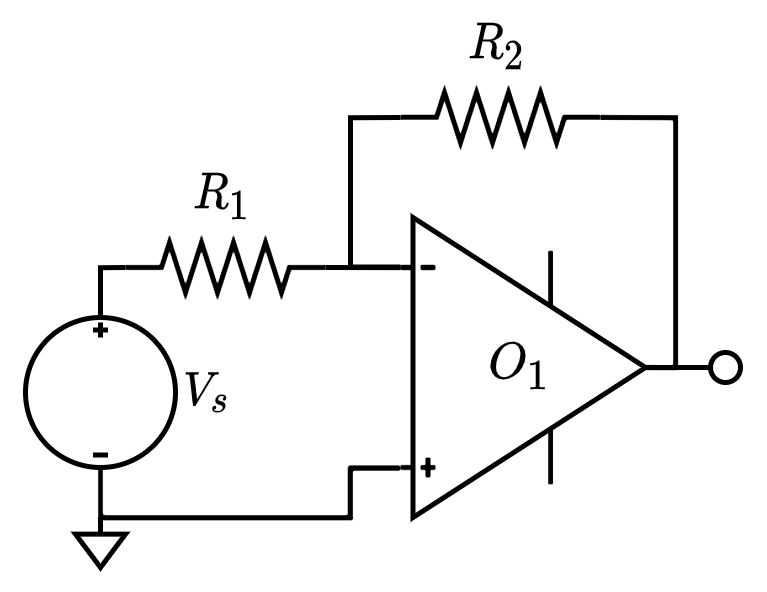

ELAB.analyze(circuit)

Symbolic analysis successful (0.210827 sec).


circuit.symbolic_node_voltages

$$ans = \left(\begin{array}{c} v_{1}=\mathrm{Vs}\\ v_{2}=0\\ v_{3}=-\frac{R_{2}\,\mathrm{Vs}}{R_{1}} \end{array}\right)$$

### 2. Inverting op-amp with additional reactive elements.

This is a slightly more complex example. We are still dealing with an inverting amplifier configuration.

circuit = Circuit('circuits/rc_op_amp.txt');
circuit.list

ans =     'Vs 1 0 AC Vs
     R1 1 2 20000
     R2 3 4 20000
     C1 2 3 C1
     C2 3 4 C2
     O1 0 3 4
     '


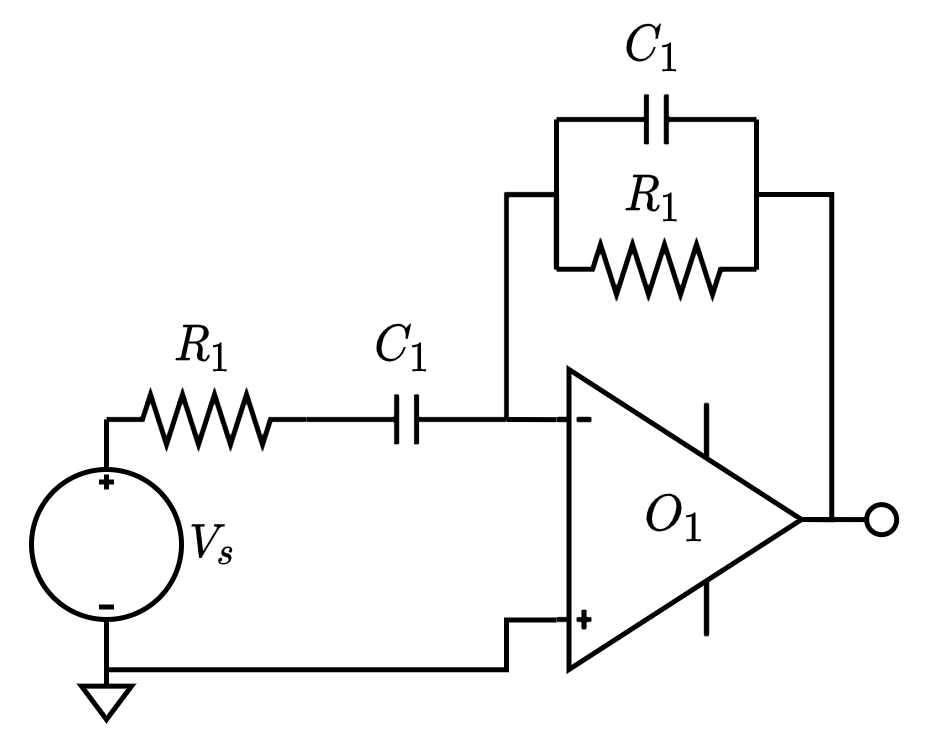

Suppose we want to know what values for the capacitors, we need to choose, to achieve poles at $p_1 =-1000\;\mathrm{rad}/s$ and $p_2 =-5000\;\textrm{rad}/s$.

ELAB.ec2sd(circuit,1,4)

Symbolic analysis successful (0.383169 sec).
Symbolic transfer function calculated successfully (3.916859e-01 sec).


$$ans = \frac{v_{4}}{v_{1}}=-\frac{C_{1}\,R_{2}\,s}{\left(C_{1}\,R_{1}\,s+1\right)\,\left(C_{2}\,R_{2}\,s+1\right)}$$

From this transfer function, it is immediately apparent, that if $R_1 =R_2 =20k\Omega$, then $C_1 =1/1000R_1 =0\ldotp 05\mu F$ and $C_2 =1/5000=0\ldotp 01\mu F$.

circuit.Capacitors(1).capacitance = 0.05e-6;

ans = 5.0000e-08

circuit.Capacitors(2).capacitance = 0.01e-6;

circuit = Circuit('circuits/rc_op_amp_num.txt');
TF = ELAB.ec2tf(circuit,1,4)

Symbolic analysis successful (0.350098 sec).

Numerical evaluation successful (0.0874597 sec).
Transfer function object created successfully (1.211225e-01 sec).

TF =
 
        -5000 s
  -------------------
  s^2 + 6000 s + 5e06
 
Continuous-time transfer function.



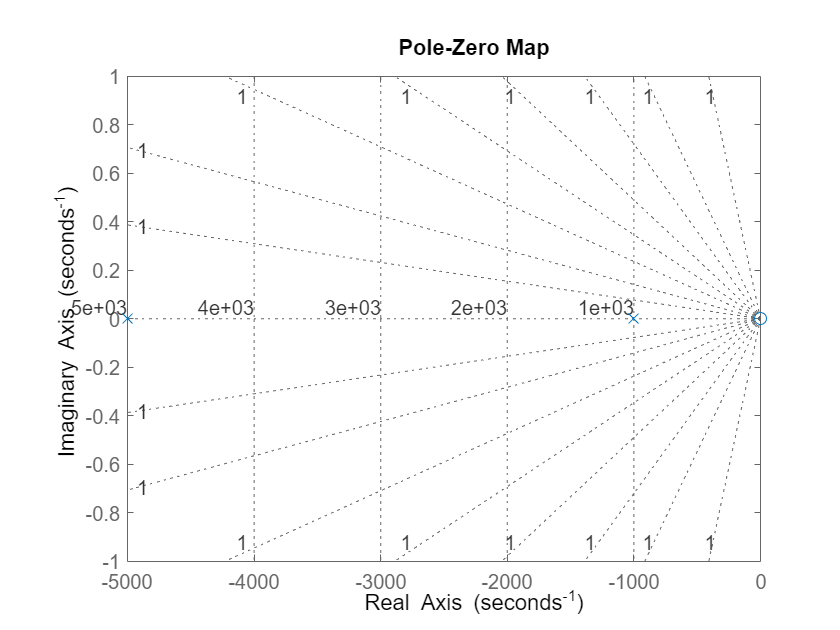

pzmap(TF); grid on;

circuit = Circuit('circuits/state_variable_filter.txt');
circuit.list

ans =     'Vs 1 0 AC Vs
     R1 1 2 1000
     R2 2 6 19000
     R3 3 4 10000
     R4 3 8 10000
     R5 4 5 16000
     R6 6 7 16000
     C1 5 6 0.00000001
     C2 7 8 0.00000001
     O1 2 3 4
     O2 0 5 6
     O3 0 7 8
     '


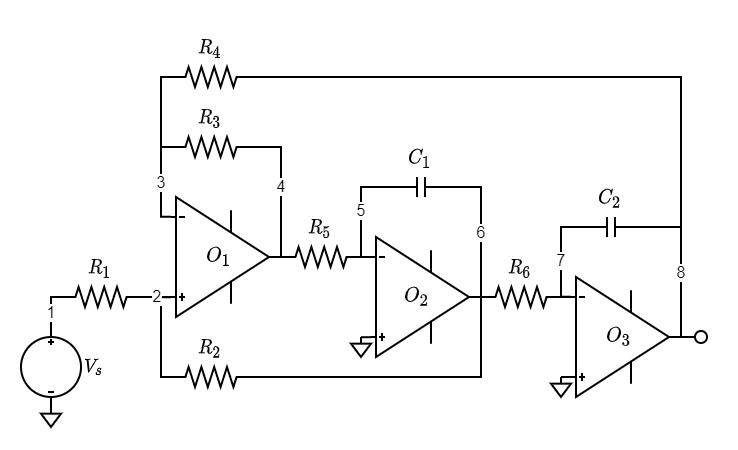

bode(ELAB.ec2tf(circuit,1,4)); grid on; hold on;

Symbolic analysis successful (1.07754 sec).

Numerical evaluation successful (0.241102 sec).
Transfer function object created successfully (2.675553e-01 sec).


bode(ELAB.ec2tf(circuit,1,6));

Transfer function object created successfully (2.028830e-02 sec).


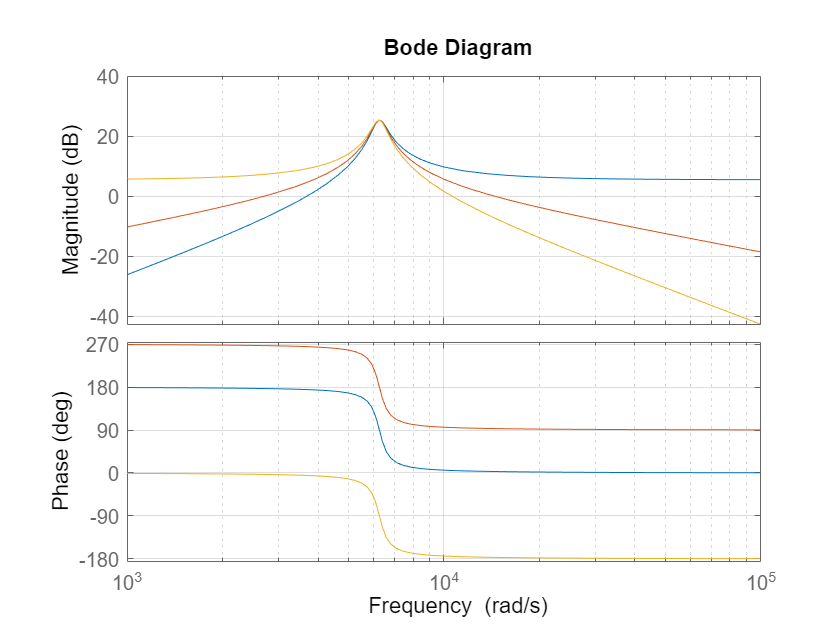

Transfer function object created successfully (1.757560e-02 sec).


bode(ELAB.ec2tf(circuit,1,8)); hold off;

ELAB.ec2sd(circuit,1,8)

Symbolic transfer function calculated successfully (5.072700e-03 sec).


$$ans = \frac{v_{8}}{v_{1}}=\frac{R_{2}\,\left(R_{3}+R_{4}\right)}{R_{1}\,R_{3}+R_{2}\,R_{3}+C_{2}\,R_{1}\,R_{3}\,R_{6}\,s+C_{2}\,R_{1}\,R_{4}\,R_{6}\,s+C_{1}\,C_{2}\,R_{1}\,R_{4}\,R_{5}\,R_{6}\,s^{2}+C_{1}\,C_{2}\,R_{2}\,R_{4}\,R_{5}\,R_{6}\,s^{2}}$$